% Creating Random Set of Variables
set = randn(10,2)

set =     0.5377   -1.3499
    1.8339    3.0349
   -2.2588    0.7254
    0.8622   -0.0631
    0.3188    0.7147
   -1.3077   -0.2050
   -0.4336   -0.1241
    0.3426    1.4897
    3.5784    1.4090
    2.7694    1.4172



n = numel(set)./2

n = 10

x = set(:,1)

x =     0.5377
    1.8339
   -2.2588
    0.8622
    0.3188
   -1.3077
   -0.4336
    0.3426
    3.5784
    2.7694


y = set(:,2)

y =    -1.3499
    3.0349
    0.7254
   -0.0631
    0.7147
   -0.2050
   -0.1241
    1.4897
    1.4090
    1.4172


xy = x.*y

xy =    -0.7258
    5.5657
   -1.6386
   -0.0544
    0.2278
    0.2680
    0.0538
    0.5104
    5.0421
    3.9248


xsq = x.^2

xsq =     0.2891
    3.3631
    5.1024
    0.7433
    0.1016
    1.7100
    0.1880
    0.1174
   12.8049
    7.6698



sumx = sum(x)

sumx = 6.2428

sumy = sum(y)

sumy = 7.0489

sumxy = sum(xy)

sumxy = 13.1740

sumxsq = sum(xsq)

sumxsq = 32.0897


scatter(x,y)
hold on

% Calculating LSRL
m = (n.*sumxy - sumx.*sumy)/(n.*sumxsq - (sumx).^2)

m = 0.3112

b = (1./n).*(sumy - m.*sumx)

b = 0.5106

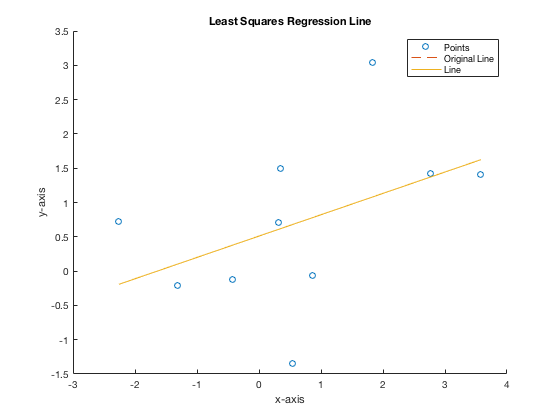

y0 = m.*x + b;

xcalc = [ones(length(x),1) x];
bcalc = xcalc\y;
Ycalc = xcalc*bcalc;
plot(x,Ycalc,'--')

% PLotting LSRL
plot(x,y0)
title('Least Squares Regression Line')
legend('Points','Original Line','Line')
xlabel('x-axis')
ylabel('y-axis')
hold off


%Calculating Residuals
Res1 = y(1) - y0(1)

Res1 = -2.0278

Res2 = y(2) - y0(2)

Res2 = 1.9536

Res3 = y(3) - y0(3)

Res3 = 0.9177

Res4 = y(4) - y0(4)

Res4 = -0.8420

Res5 = y(5) - y0(5)

Res5 = 0.1049

Res6 = y(6) - y0(6)

Res6 = -0.3086

Res7 = y(7) - y0(7)

Res7 = -0.4998

Res8 = y(8) - y0(8)

Res8 = 0.8725

Res9 = y(9) - y0(9)

Res9 = -0.2152

Res10 = y(10) - y0(10)

Res10 = 0.0447


% Plotting Residuals
Residuals = [Res1,Res2,Res3,Res4,Res5,Res6,Res7,Res8,Res9,Res10]

Residuals =    -2.0278    1.9536    0.9177   -0.8420    0.1049   -0.3086   -0.4998    0.8725   -0.2152    0.0447


ResSum = sum(Residuals)

ResSum = -1.5543e-15

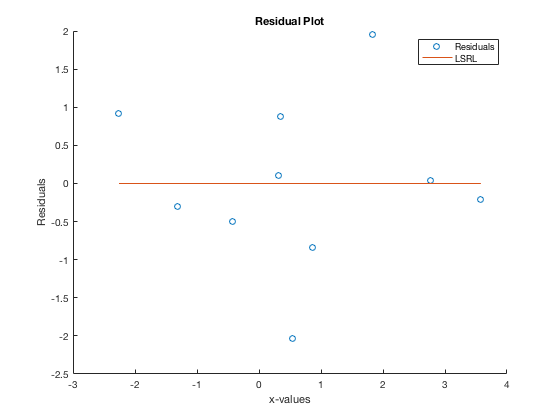

scatter(x,Residuals)
hold on
yr = 0.*x;
plot(x,yr)
title('Residual Plot')
legend('Residuals','LSRL')
xlabel('x-values')
ylabel('Residuals')


% Finding the Sum of Sqaured Errors
ResSq = (Residuals).^2

ResSq =     4.1121    3.8166    0.8422    0.7089    0.0110    0.0953    0.2498    0.7612    0.0463    0.0020


SumOfSquaredErrors = sum(ResSq)

SumOfSquaredErrors = 10.6454